# Wheel Turning Speed Analysis

In the experiment reported by [Steinmetz et al, 2019 in Nature](https://www.nature.com/articles/s41586-019-1787-x), the mice perform a discrimination task where that had to find out which stimuli (left vs right) has the higher contrast. And they report their  decision by steering a wheel such that the stimuli with the higher  contrast moves to the center screen.

**Analysis Goals**

In this notebook we will be analyzing the speed at which the mouse turned the wheel to report their decision.

**Learning Goals**

- Work with `structs` 

- Filter data in a table

- Produce line plots

- Make formatted print statements

## Visualising Wheel Turning Speed

In this section we will plot the speed at which the mouse turned the  wheel in every trial. 

The experimental data contains the wheel speed over time, across all  trials. A positive turning speed means that the wheel is being moved to  the right, while a negative speed tells us the wheel is being moved to  the left. When the wheel is not being moved at all, the turning speed is zero. 

The wheel speed data is binned in bins of 10ms, meaning the difference in time between each datapoint is 10ms.

data = readtable("data/Cori_14-12-2016_wheel.xml");

**Example Exercise**

Plot the wheel speed against time for trial 7 

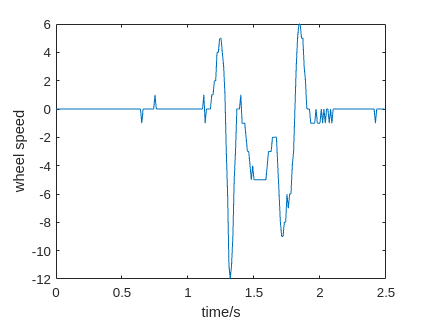

plot_data = data{data.trial==7,'wheel_speed'};
time_bins = 0:0.01:2.49; % times in ms
plot(time_bins,plot_data)

xlabel('time/s')
ylabel('wheel speed')

Plot the wheel speed against time for trial 99

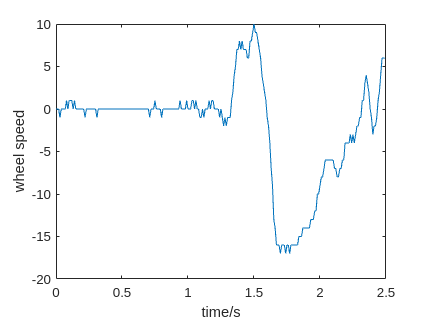

plot_data = data{data.trial==99,'wheel_speed'};
plot(time_bins,plot_data)

xlabel('time/s')
ylabel('wheel speed')

Plot the wheel speed against time for the last trial (ie. the largest trial number) in the data. There are many ways to do this!

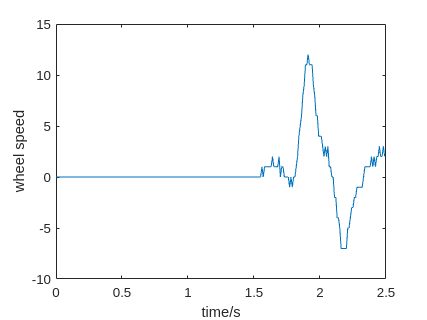

plot_data = data{data.trial==max(data.trial),'wheel_speed'};
plot(time_bins,plot_data)

xlabel('time/s')
ylabel('wheel speed')

Make a figure showing the wheel speeds of both trials 26 and 27. **Hint** - you will need to use the following pattern: 

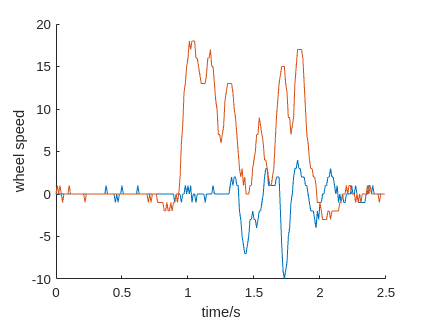

plot_data_t26 = data{data.trial==26,'wheel_speed'};
plot_data_t27 = data{data.trial==27,'wheel_speed'};

clf
hold on
plot(time_bins,plot_data_t27)
plot(time_bins,plot_data_t26)

xlabel('time/s')
ylabel('wheel speed')
hold off

Recreate the above plot adding legend labels to the lines

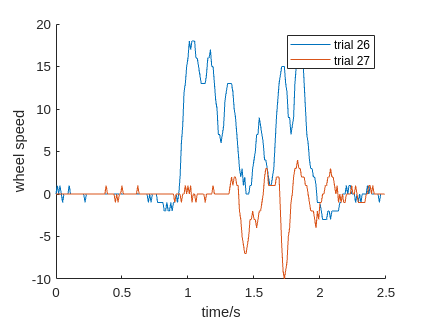

plot_data_t26 = data{data.trial==26,'wheel_speed'};
plot_data_t27 = data{data.trial==27,'wheel_speed'};

clf
hold on
plot(time_bins,plot_data_t26, "DisplayName","trial 26")
plot(time_bins,plot_data_t27,"DisplayName","trial 27")

xlabel('time/s')
ylabel('wheel speed')
legend()
hold off

Looks good! But the legend does obscure the data. Change the position of the legend. **Hint** run 

to view an explanation of possible options that can be given to` legend()`

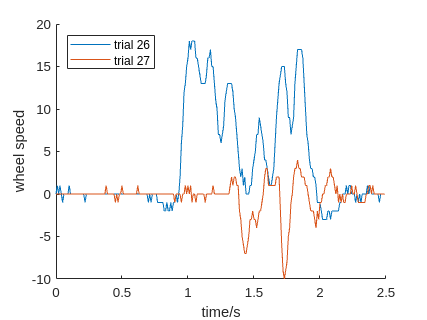

plot_data_t26 = data{data.trial==26,'wheel_speed'};
plot_data_t27 = data{data.trial==27,'wheel_speed'};

clf
hold on
plot(time_bins,plot_data_t26, "DisplayName","trial 26")
plot(time_bins,plot_data_t27,"DisplayName","trial 27")

xlabel('time/s')
ylabel('wheel speed')
legend("Location", "northwest")
hold off

## Describing Data with Metrics: Determining Turning Direction

Data analysis is all about making sense of data. Statistics like  averages is one example of this. Such measures can help us minimise the  amount of data that we need to think about and allow to answer more  generic questions. In the context of the wheel speed data that we have  been working on so far, a natural question is: **which way did the subject turn the wheel?**

In this section, we will be using aggregation methods such as `mean()` combined with filtering to further analyze the wheel speed data for  instance to only look at trials in which the wheel was turned to the  left.

What is the size of the wheel speed data?

size(data.wheel_speed)

ans =    214   250


That means that we have 214 trials and each trial has 250 datapoints of wheel speed. 

Say if we want to find the average wheel speed for each trial, we would then have 214 values

What is the size of the result `mean(data.wheel_speed)`?

size(mean(data.wheel_speed))

ans =      1   250


By default MATLAB calculates the mean across the columns of the table. We are interested however in the mean across the rows. 

This is given by changing the axis across which the mean is calculated. By default the axis is 1, like this

mean(data.wheel_speed,1)

ans =     0.1028    0.0701    0.0701    0.0280    0.0187    0.0187   -0.0234    0.0467    0.0047    0.0047   -0.0047   -0.0093   -0.0327    0.0374    0.0047   -0.0093    0.0093    0.0187         0   -0.0140    0.0280    0.0140   -0.0047    0.0047    0.0140         0   -0.0140   -0.0047   -0.0047    0.0093         0    0.0140   -0.0140   -0.0093    0.0140         0         0   -0.0093   -0.0093         0   -0.0140         0    0.0187   -0.0093    0.0140   -0.0047   -0.0093         0         0    0.0374


Calculate the mean wheel speed for each trial. Name the result `mean_wheel_speeds`

mean_wheel_speeds = mean(data.wheel_speed,2);

Make a new column in data "mean_wheel_speed" which holds the values of  `mean_wheel_speeds`

data.mean_wheel_speed = mean_wheel_speeds;